### ***1.3 - Fourier transform of a recorded signal***

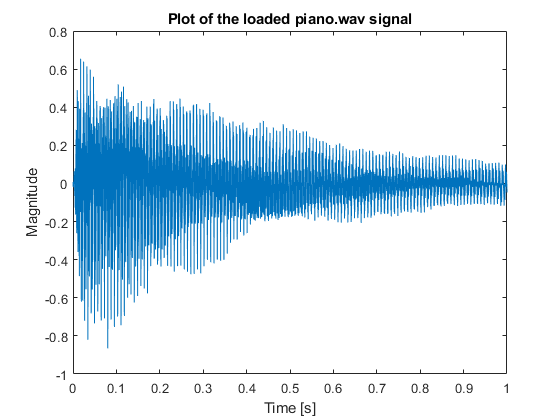

clear all
close all hidden
[piano, fs_loaded] = audioread([pwd filesep 'piano.wav']);
t_piano = (1:length(piano))/fs_loaded;

% plot the loaded signal
figure(12)
plot(t_piano,piano, '-')
xlim([0,1])
xlabel('Time [s]')
ylabel('Magnitude')
title('Plot of the loaded piano.wav signal')

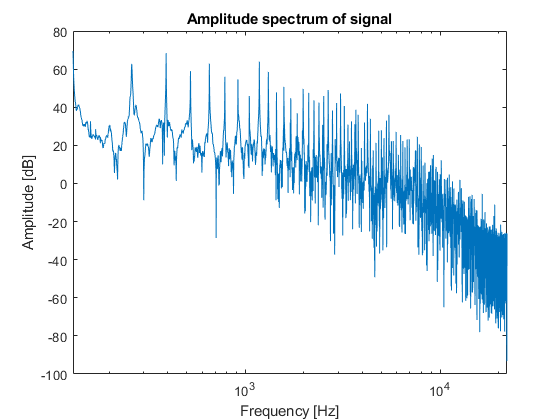


% construct the frequency spectrum of the loaded signal 
[Y_loaded, freq_loaded] = make_spectrum(piano, fs_loaded);
magdb_loaded = 20*log10(abs(Y_loaded));

% lets find the fundemental freq
index = find(magdb_loaded == max(magdb_loaded));
f_0 = freq_loaded(max(index));
% N should be 169 for max hifi but no more
N = 100;

% plot the freq spectrum of the loaded signal
figure(13)
semilogx(freq_loaded,magdb_loaded,'-')
xlim([f_0,fs_loaded/2]);
% ylim([-80,0])
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
title('Amplitude spectrum of signal')

After probing the figure of the amplitude spectrum, the fundamental frequency (the one with the highest amplitude) seems to be approx. 130 Hz.

*Synthesis in frequency domain...*

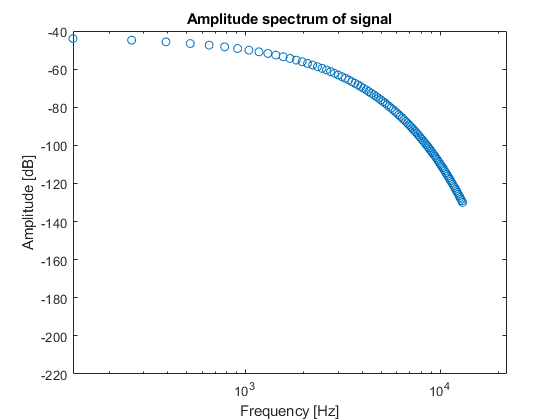

%make harmonic vector
y_harmonics = ones(1,441000);
f_harmonics = ones(1,441000);


% estimate the frequency envelope - looking at the plot above
for k = 1:N
    f_harmonics(k) = f_0*k;
    y_harmonics(k) = 0.007*exp(-k*1/10);
end

% lets make a lot of sine waves that are multiplums of 130 Hz 
sine_waves = ones(N,fs_loaded*10);
for k = 1:N
    [t_sines,sine_waves(k,:)] = generate_sinusoid(y_harmonics(k),k*f_0,0,fs_loaded,10);
end


magdb_y_harmonics = 20*log10(abs(y_harmonics));
figure(14);
semilogx(f_harmonics,magdb_y_harmonics,'o')
xlim([f_0,fs_loaded/2]);
ylim([-220,-40])
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
title('Amplitude spectrum of signal')

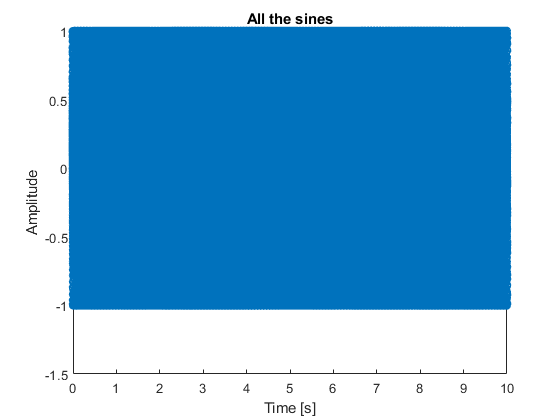



sum_sines = zeros(1,fs_loaded*10);
for k = 1:N
    sum_sines(1,:) = sum_sines(1,:) + (sine_waves(k,:))/N;
end

%normalize envelope! 
sum_sines = sum_sines/max(sum_sines);

figure(120);
plot(t_sines,sum_sines,'o')
% xlim([f_0,fs_loaded/2]);
% ylim([-220,-40])
xlabel('Time [s]')
ylabel('Amplitude')
title('All the sines')

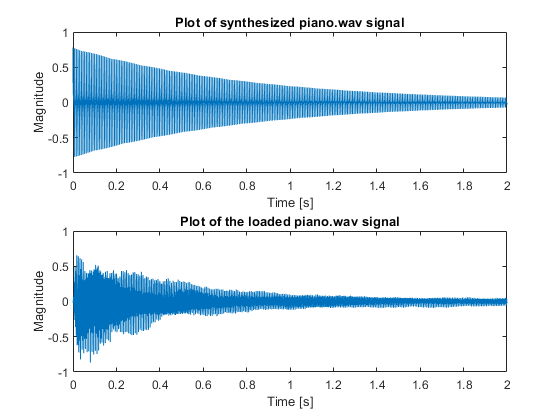


% time dependent amplitude is this exponential function
for k = 1:441000
    synthesized_signal(k) = sum_sines(k)*0.78*exp(-1.2*k/fs_loaded);
end 

% sound(synthesized_signal,fs_loaded)

% plot the signals
figure(16)
subplot(2,1,1)
plot(t_sines(2:2:end),synthesized_signal(2:2:end),'-')
ylim([-1,1])
xlim([0,2])
xlabel('Time [s]')
ylabel('Magnitude')
title('Plot of synthesized piano.wav signal')

subplot(2,1,2)
plot(t_piano,piano, '-')
xlim([0,2])
ylim([-1,1])
xlabel('Time [s]')
ylabel('Magnitude')
title('Plot of the loaded piano.wav signal')